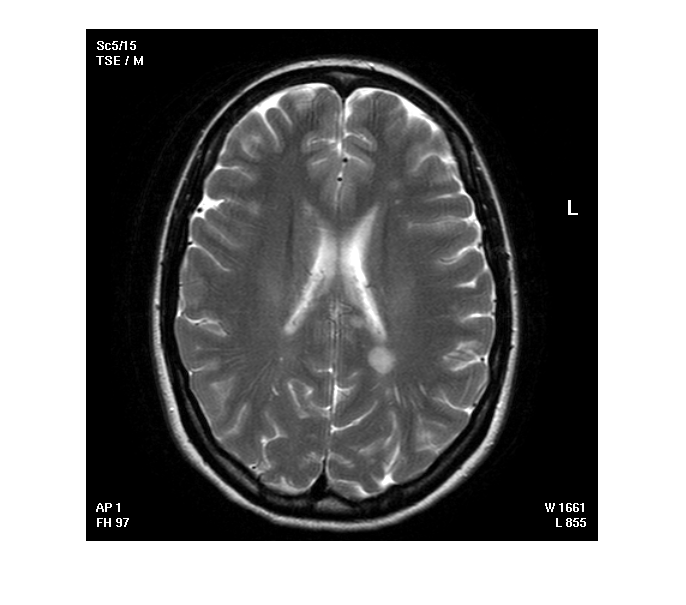

%load('IM_00240.plq','-mat');
X=imread('IM_00240.TIF');
%[X, map] = dicomread('US-PAL-8-10x-echo.dcm');
%montage(X, map, 'Size', [2 5]);
imshow(X)

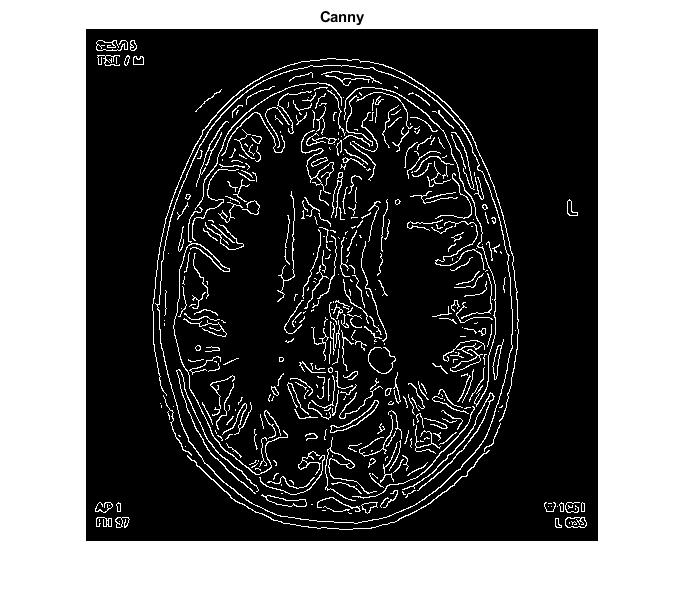

BW1 = edge(X,'Canny');
BW2 = edge(X,'Prewitt');
BW3 = edge(X,'sobel');
%Texture
E = entropyfilt(I);
Eim = rescale(E);
BW4 = imbinarize(Eim, .8);
%plot
%subplot(2,2,1);
imshow(BW1);title('Canny');

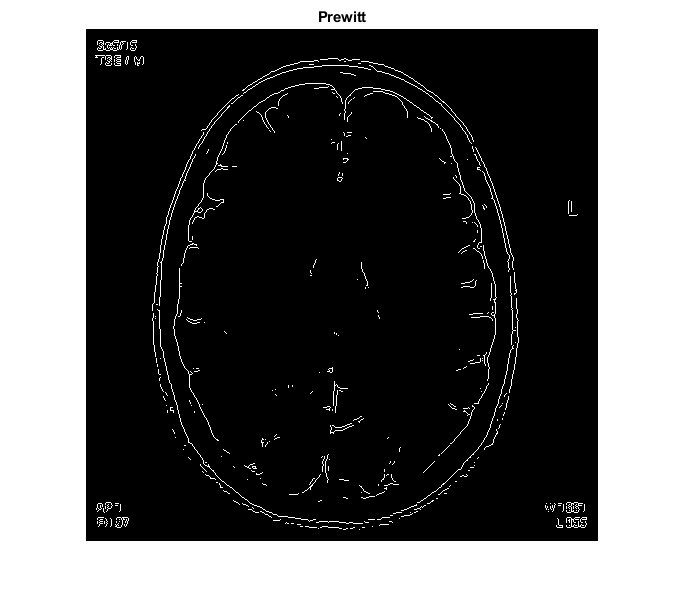

%subplot(2,2,2);
imshow(BW2);title('Prewitt');

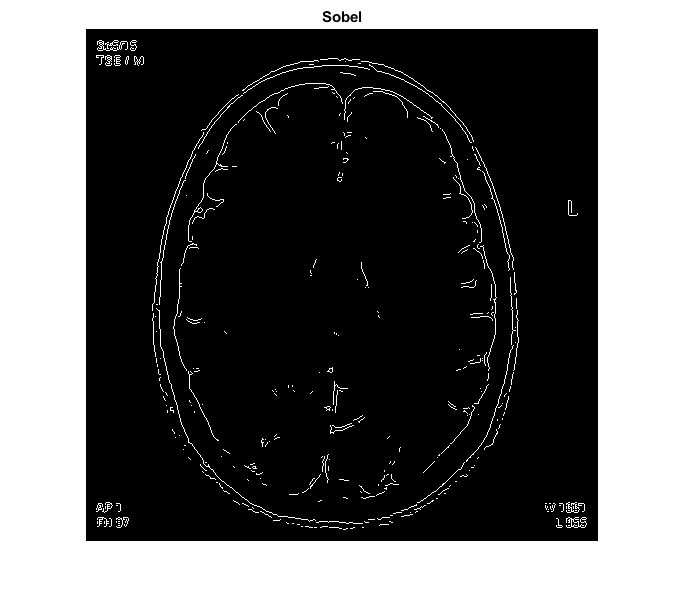

%subplot(2,2,3);
imshow(BW3);title('Sobel');

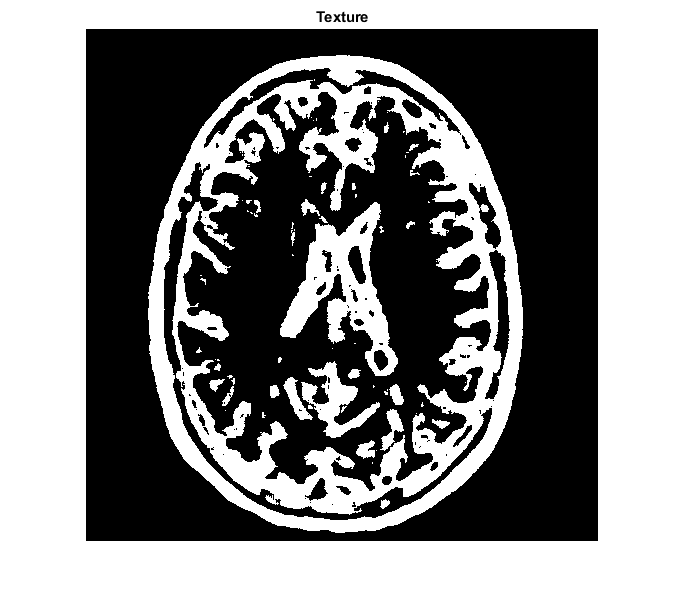

%subplot(2,2,4)
imshow(BW4);title('Texture')